# Lab 8 - Uncertaintity in MDA

Jared Ham

The 4 tool functions are shown below. 

Tool 1: Describes mass balance of the aircraft according to the following equation:


$$m_t =100+m_f +6*S_w +800$$


Where $m_t$ is total aircraft mass, $m_f \;$is fuel mass and $S_w$ is wing area in square meters

Tool 2 describes the lift force - assumes no acceleration in the y direction:


$$L=9\ldotp 81*m_t$$


Tool 3 describes the velcoity of the aircraft - again asumes no acceleration and a $C_l$ of 0.5 and assumes a single altitude where air density = 1.2 $\frac{\textrm{kg}}{m^3 }$

Tool 4 describes the energy consumption of the aircraft. Assumes a $C_d$ of 0.025,  a BSFC of 400$\frac{g}{\textrm{kW}*\textrm{hr}}$ and propeller efficiency of 0.85

Now lets use these tools to solve the system of equations using MatLabs fsolve function:

CA_vars_converged = fsolve('List_of_CAs',CA_vars_guess,optimset('Display','iter','MaxFunEvals',1000),des_vars)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5     1.07006e+06                      1.04e+03               1
     1         10      1.0673e+06              1       1.03e+03               1
     2         15     1.06078e+06            2.5       1.03e+03             2.5
     3         20      1.0464e+06           6.25       1.01e+03            6.25
     4         25     1.01587e+06         15.625            979            15.6
     5         30          944473        39.0625            909            39.1
     6         35          880498        97.6562       1.66e+03            97.7
     7         40          798088        244.141            774             244
     8         45          672845        610.352       1.34e+03             610
     9         50          454228        1525.88            535        1.53e+03
    10         55          120075         3

CA_vars_converged = 	1.0e+04 *

    0.1062    1.0421    0.0039    0.0028


With design variables of $S_w =22\ldotp 4\;m^2$ and $t=4\;\textrm{hours}$ the result is a plane with the following parameters:


$$\begin{array}{l}
m_t =1062\;\textrm{kg}\;\\
V=39\frac{m}{s^2 }\\
m_f =28\textrm{kg}
\end{array}$$


Ok that result is great and all, but how much confidence do we have in each of those numbers? Well we need to perform a System Sensitivity Analysis to find out. 

Let's first run the code from Dr. Bradley to perform the SSA with all of the tool and input uncertaintities set to 0. We will expect the same results above with output of uncertainties of 0.  To allow for easy running of the code with different input parameters, I created a function out of the m file. 

 
 
 
Number of variables in each tool, each column is a tool
 
Tool x Variable
 


num_des_vars =      1     0     1     2


num_CA_inputs =      1     1     1     1


num_CA_outputs =      1     1     1     1


num_CAs = 4

num_CA_vars =      1     1     1     1


design_vars_in =      1     0
     0     0
     1     0
     1     1


CA_in =      0     0     0     1
     1     0     0     0
     0     1     0     0
     0     0     1     0


CA_out =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


CA_list_sorted_ordered = 4×1 cell array
    {'mt'}
    {'L' }
    {'V' }
    {'mf'}

design_vars_list_sorted_ordered = 2×1 cell array
    {'Sw'}
    {'t' }

design_vars_errors_sorted_ordered =     0.1000         0


CA_outputs_errors_sorted_ordered =     0.0200    0.0100    0.2000    0.0500


ca_names_list = 1×4 cell array
    {'tool1'}    {'tool2'}    {'tool3'}    {'tool4'}


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5         43404.6                      1.95e+03               1
     1         10         39583.9              1       1.85e+03               1
     2         15         30890.7            2.5       1.61e+03             2.5
     3         20         14521.1           6.25            996            6.25
     4         25            3953         15.625           55.2            15.6
     5         30         1429.37        39.0625            195            39.1
     6         35         554.719        97.6563           24.4            97.7
     7         40         10.3818        244.141           10.3             244
     8         45       0.0001154        49.1087         0.0229             610
     9         50     4.72117e-17       0.108457       7.28e-09             610



CA_vars = 	1.0e+04 *

    0.1062    1.0421    0.0039    0.0028


These uncertainties are input to the SSA:
1) Tool uncertainties:


uncertT_fraction =     0.0200
    0.0100
    0.2000
    0.0500


2) Design variable uncertainties:


uncertX_fraction =     0.1000
         0


These uncertainties are output from the SSA:
1) Uncertainties in the CA variables, [ mt L V mf  ]:


uncertY_fraction =     0.0300
    0.0318
    0.2150
    0.6555


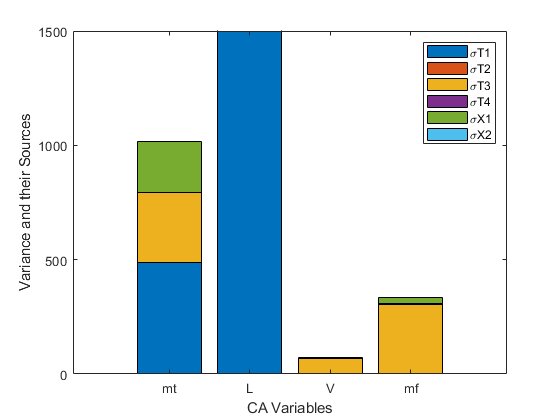

CA_vars_guess = [1000,10000,50,50];
design_vars = [22.4, 4.0];
SSA(design_vars, CA_vars_guess)

CA_vars_guess = [1000,10000,50,50];
design_vars = [22.4, 4.0];
SSA(design_vars, CA_vars_guess)

 
 
 
Number of variables in each tool, each column is a tool
 
Tool x Variable
 


num_des_vars =      1     0     1     2


num_CA_inputs =      1     1     1     1


num_CA_outputs =      1     1     1     1


num_CAs = 4

num_CA_vars =      1     1     1     1


design_vars_in =      1     0
     0     0
     1     0
     1     1


CA_in =      0     0     0     1
     1     0     0     0
     0     1     0     0
     0     0     1     0


CA_out =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


CA_list_sorted_ordered = 4×1 cell array
    {'mt'}
    {'L' }
    {'V' }
    {'mf'}

design_vars_list_sorted_ordered = 2×1 cell array
    {'Sw'}
    {'t' }

design_vars_errors_sorted_ordered =     0.1000         0


CA_outputs_errors_sorted_ordered =     0.0200    0.0100    0.2000    0.0500


ca_names_list = 1×4 cell array
    {'tool1'}    {'tool2'}    {'tool3'}    {'tool4'}


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5         43404.6                      1.95e+03               1
     1         10         39583.9              1       1.85e+03               1
     2         15         30890.7            2.5       1.61e+03             2.5
     3         20         14521.1           6.25            996            6.25
     4         25            3953         15.625           55.2            15.6
     5         30         1429.37        39.0625            195            39.1
     6         35         554.719        97.6563           24.4            97.7
     7         40         10.3818        244.141           10.3             244
     8         45       0.0001154        49.1087         0.0229             610
     9         50     4.72117e-17       0.108457       7.28e-09             610



CA_vars = 	1.0e+04 *

    0.1062    1.0421    0.0039    0.0028


These uncertainties are input to the SSA:
1) Tool uncertainties:


uncertT_fraction =     0.0200
    0.0100
    0.2000
    0.0500


2) Design variable uncertainties:


uncertX_fraction =     0.1000
         0


These uncertainties are output from the SSA:
1) Uncertainties in the CA variables, [ mt L V mf  ]:


uncertY_fraction =     0.0300
    0.0318
    0.2150
    0.6555


 
 
 
Number of variables in each tool, each column is a tool
 
Tool x Variable
 


num_des_vars =      1     0     1     2


num_CA_inputs =      1     1     1     1


num_CA_outputs =      1     1     1     1


num_CAs = 4

num_CA_vars =      1     1     1     1


design_vars_in =      1     0
     0     0
     1     0
     1     1


CA_in =      0     0     0     1
     1     0     0     0
     0     1     0     0
     0     0     1     0


CA_out =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


CA_list_sorted_ordered = 4×1 cell array
    {'mt'}
    {'L' }
    {'V' }
    {'mf'}

design_vars_list_sorted_ordered = 2×1 cell array
    {'Sw'}
    {'t' }

design_vars_errors_sorted_ordered =     0.1000         0


CA_outputs_errors_sorted_ordered =     0.0200    0.0100    0.2000    0.0500


ca_names_list = 1×4 cell array
    {'tool1'}    {'tool2'}    {'tool3'}    {'tool4'}


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5         37188.2                      1.89e+03               1
     1         10         33476.3              1        1.8e+03               1
     2         15         25055.8            2.5       1.55e+03             2.5
     3         20         9374.82           6.25            942            6.25
     4         25     0.000105424        15.2732         0.0236            15.6
     5         30     1.20133e-17       0.107781       8.18e-09            38.2

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

CA_vars = 	1.0e+03 *

    1.0190    9.9963    0.0497    0.0380


These uncertainties are input to the SSA:
1) Tool uncertainties:


uncertT_fraction =     0.0200
    0.0100
    0.2000
    0.0500


2) Design variable uncertainties:


uncertX_fraction =     0.1000
         0


These uncertainties are output from the SSA:
1) Uncertainties in the CA variables, [ mt L V mf  ]:


uncertY_fraction =     0.0337
    0.0353
    0.2187
    0.6668


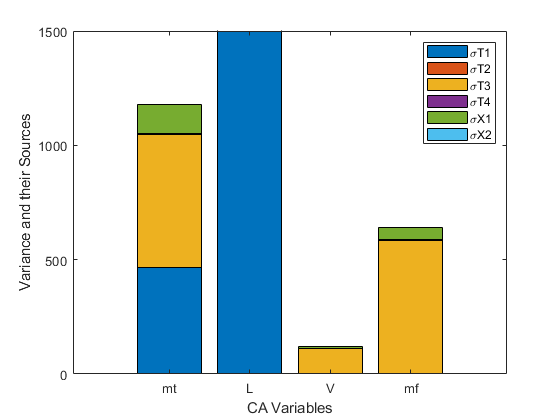

CA_vars_guess = [1000,10000,50,50];
design_vars = [13.5, 4.5];
SSA(design_vars, CA_vars_guess)

## Task 4 - Homework

### Problem 1 

Present the converged solution of the MDA. What are the values of each of the CA variables at a relevant set of values of the design variables? You can choose DVs that are of interest to you

For this problem lets assume we are designing the Cirrus SR22 airplane pictured below and specs taken from [here](https://www.planeandpilotmag.com/article/2004-cirrus-sr22-g2/#.XpYha8hKiUk): 

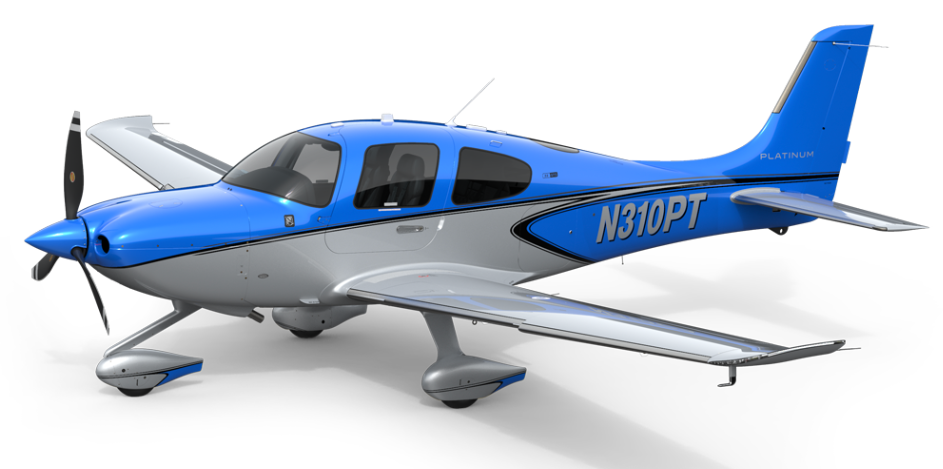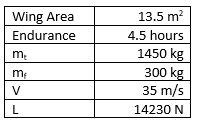

CA_vars_guess = [1000,10000,50,50];
design_vars = [13.5, 4.5];
CA_vars_converged = fsolve('List_of_CAs',CA_vars_guess,optimset('Display','iter','MaxFunEvals',1000),design_vars)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5         37188.2                      1.89e+03               1
     1         10         33476.3              1        1.8e+03               1
     2         15         25055.8            2.5       1.55e+03             2.5
     3         20         9374.82           6.25            942            6.25
     4         25     0.000105424        15.2732         0.0236            15.6
     5         30     1.20133e-17       0.107781       8.18e-09            38.2

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

CA_vars_converged = 	1.0e+03 *

    1.0190    9.9963    0.0497    0.0380


Running the simulation with the design vars specified above gave the following results, with the outputs of the simulation bolded. 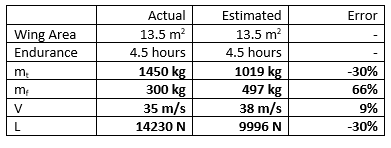

For the crudeness of the model that was used to predict the total mass, fuel mass, velocity and lift I would say that the model did a pretty good job of estimating. The largest error if 66% for fuel mass. At first glance without running any uncertaintity analysis I would say that this model does its job as intended. Which is to give a good starting design point for moving into a more detailed design process. 

### Problem 2

Present the results of the SSA in terms of the relevant total relative uncertainty in mt, and the contributors of uncertainty to mt. Make sure you make a nice plot to show me the contributors to uncertainty in mt. If you could spend money and time to reduce one of the tool errors or one of the design variables errors, which tool or design variable would you choose, and why?

 
 
 
Number of variables in each tool, each column is a tool
 
Tool x Variable
 


num_des_vars =      1     0     1     2


num_CA_inputs =      1     1     1     1


num_CA_outputs =      1     1     1     1


num_CAs = 4

num_CA_vars =      1     1     1     1


design_vars_in =      1     0
     0     0
     1     0
     1     1


CA_in =      0     0     0     1
     1     0     0     0
     0     1     0     0
     0     0     1     0


CA_out =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


CA_list_sorted_ordered = 4×1 cell array
    {'mt'}
    {'L' }
    {'V' }
    {'mf'}

design_vars_list_sorted_ordered = 2×1 cell array
    {'Sw'}
    {'t' }

design_vars_errors_sorted_ordered =     0.1000         0


CA_outputs_errors_sorted_ordered =     0.0200    0.0100    0.2000    0.0500


ca_names_list = 1×4 cell array
    {'tool1'}    {'tool2'}    {'tool3'}    {'tool4'}


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5         37188.2                      1.89e+03               1
     1         10         33476.3              1        1.8e+03               1
     2         15         25055.8            2.5       1.55e+03             2.5
     3         20         9374.82           6.25            942            6.25
     4         25     0.000105424        15.2732         0.0236            15.6
     5         30     1.20133e-17       0.107781       8.18e-09            38.2

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

CA_vars =     1.0190    9.9963    0.0497    0.0380


These uncertainties are input to the SSA:
1) Tool uncertainties:


uncertT_fraction =     0.0200
    0.0100
    0.2000
    0.0500


2) Design variable uncertainties:


uncertX_fraction =     0.1000
         0


These uncertainties are output from the SSA:
1) Uncertainties in the CA variables, [ mt L V mf  ]:


uncertY_fraction =     0.0337
    0.0353
    0.2187
    0.6668


CA_vars_guess = [1000,10000,50,50];
design_vars = [13.5, 4.5];
SSA(design_vars, CA_vars_guess)

Variance and their source for each of the Contributing Analysis Outputs

Since we are most interested in the total mass output of the CA, let's examine its error further. The total mass has a total variance of about 1200 kg^2. The variance due to Tool 1 and Tool 3 contribute the most to the variance of the mass. However The variance due to tool 1 is much larger than all the other variances because it is scaled up by 10 times due to the inner workings of tool one. However the error due to Tool 3 contributes just as much to the variance in the mass out put. Error due to Tool 3 also shows up in the CA variables V and fuel mass wheras error due to Tool 1 does this. Because of these 2 factors I would choose to perform experiments to **reduce uncertaintity in Tool 3. **

### **Problem 3**

**Assume that you can reduce the relative uncertainty associated with one of the tool errors OR one of the design variables error by a factor of 5, by performing some experiment. Perform the SSA using that reduced value of uncertainty to show that your experimental will be successful in reducing both the total uncertainty and allocation of uncertainty to mt, as you expected.**

Let's assume that we went out and did some experiments relating to tool 3 and that we were able to gather data to support that our tool is actually accurate to within 4% instead of 20%. Now lets rerun the same analysis as above, while making the change to the Tool 3 uncertaintity. 

 
 
 
Number of variables in each tool, each column is a tool
 
Tool x Variable
 

                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5         37188.2                      1.89e+03               1
     1         10         33476.3              1        1.8e+03               1
     2         15         25055.8            2.5       1.55e+03             2.5
     3         20         9374.82           6.25            942            6.25
     4         25     0.000105424        15.2732         0.0236            15.6
     5         30     1.20133e-17       0.107781       8.18e-09            38.2

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function toler

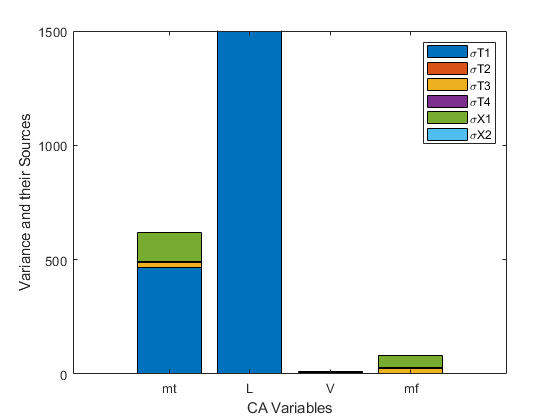

CA_vars_guess = [1000,10000,50,50];
design_vars = [13.5, 4.5];
SSA(design_vars, CA_vars_guess)

Variance and their Sources for CA Variables after reducing Tool 3 Uncertaintity

As can be seen above, by reducing the uncertaintity in Tool 3 from 20% to 4%, the variance associated with Tool 3 in the total mass of the airplane was cut in half. The total variances in CA variables V and fuel mass were also greatly reduced. I would say that money was well spent. 